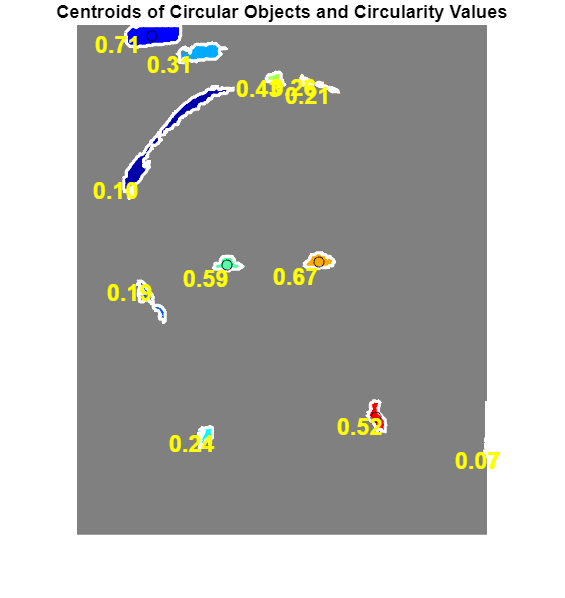

clear

%https://se.mathworks.com/help/images/identifying-round-objects.html

input = imread("db\DB0\eyedetection\db0test.png");

threshold = 150;
bi = input > threshold;

minSize = 80;
bw = bwareaopen(bi,minSize);

[B,L] = bwboundaries(bw,"noholes");

imshow(label2rgb(L,@jet,[.5 .5 .5]))
hold on
for k = 1:length(B)
  boundary = B{k};
  plot(boundary(:,2),boundary(:,1),"w",LineWidth=2)
end
title("Objects with Boundaries in White")

stats = regionprops(L,"Circularity","Centroid");

threshold = 0.5;
for k = 1:length(B)

  % Obtain (X,Y) boundary coordinates corresponding to label "k"
  boundary = B{k};
  
  % Obtain the circularity corresponding to label "k"
  circ_value = stats(k).Circularity;
  
  % Display the results
  circ_string = sprintf("%2.2f",circ_value);

  % Mark objects above the threshold with a black circle
  if circ_value > threshold
    centroid = stats(k).Centroid;
    plot(centroid(1),centroid(2),"ko");
  end
  
  text(boundary(1,2)-35,boundary(1,1)+13,circ_string,Color="y",...
       FontSize=14,FontWeight="bold")
  
end
title("Centroids of Circular Objects and Circularity Values")

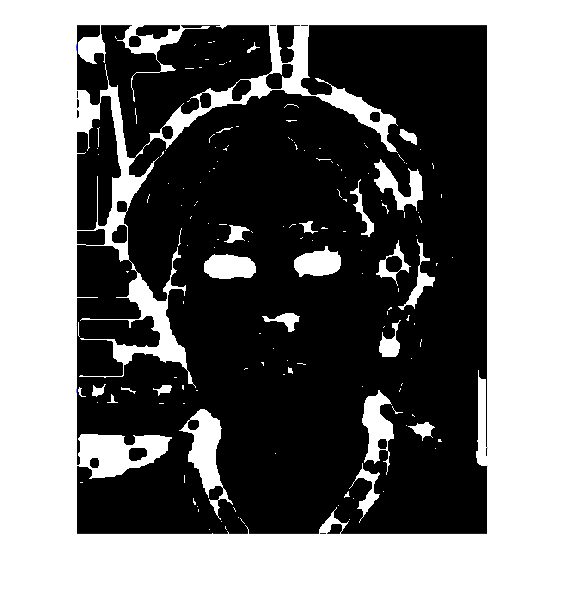

clear
input = imread("db\DB0\eyedetection\db0test.png");
r_min = 6;
r_max = 12;
sense_Val = 0.9;

imgBorder = edge(input,"sobel");

se = strel("disk",6);
bw = imclose(imgBorder,se);


[centers,radii, metric] = imfindcircles(bw,[r_min,r_max],'Sensitivity',sense_Val);
imshow(bw)
hold off

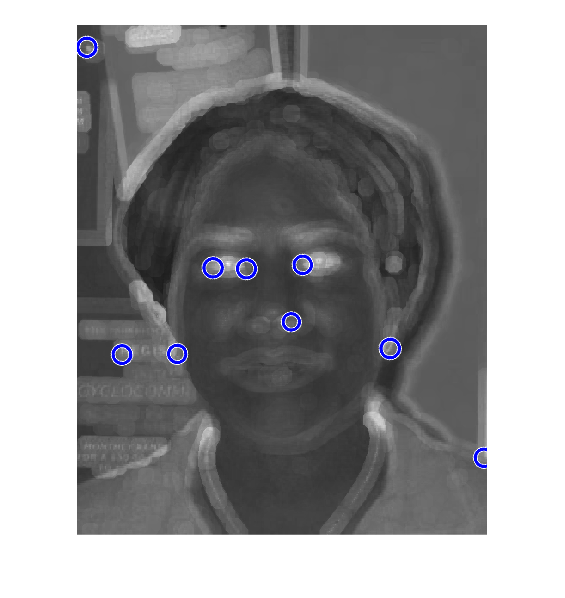

imshow(input)
hold on
viscircles(centers, radii,'EdgeColor','b');